clc
clear all
close all

## Parameters

Kernel = 'polynomial';
KernelScale = 1;
Direction = 'backward';

% 40 settimane - 86.8%
% Kernel = 'polynomial';
% KernelScale = 1.3;
% Direction = 'backward';

% 3 mesi - 82.5%
% Kernel = 'polynomial';
% KernelScale = 1;
% Direction = 'forward';

## LOAD DATA

[Dataset] = load_dataset(0,'NEG3.csv','POS3.csv'); %1 if you want to detect outliers,
%[Dataset2] = load_dataset(0,'sani3.csv','malati3.csv');

## FEATURE SELECTION

Data = Dataset{:,1:end-1}; % Parameters
Labels = Dataset{:,end}; % Labels

Sequential


%c = cvpartition(Labels,'Holdout',0.3); 
% %partiziono dataset 0,3 e' il 30% del dataset come il testset
c = cvpartition(Labels,'LeaveOut');
opts = statset('display','iter');

classf = @(train_data,train_labels,test_data,test_labels) ...
        sum(predict(fitcsvm(train_data,train_labels,'KernelFunction', Kernel, ...
        'PolynomialOrder', [], ...
        'KernelScale', KernelScale, ... 
        'BoxConstraint', 1, ...
        'Standardize', true, 'ClassNames', categorical({'NEG'; 'POS'})), test_data) ~= test_labels); 
[fs,history] = sequentialfs(classf,Data,Labels,'cv',c,'options',opts,'direction',Direction);

Start backward sequential feature selection:
Initial columns included:  all
Columns that must be included:  none
Step 1, used initial columns, criterion value 0.425
Step 2, removed column 7, criterion value 0.375
Step 3, removed column 8, criterion value 0.3
Step 4, removed column 15, criterion value 0.275
Step 5, removed column 17, criterion value 0.275
Step 6, removed column 2, criterion value 0.275
Step 7, removed column 5, criterion value 0.275
Step 8, removed column 18, criterion value 0.275
Step 9, removed column 10, criterion value 0.25
Step 10, removed column 16, criterion value 0.25
Final columns included:  1 3 4 6 9 11 12 13 14 


Dimensionality reduction

fprintf('Sono state selezionate le features:');

Sono state selezionate le features:

Dataset(1,fs)

ans = 1×9 table
    VelHandsCorrelation    JerkHandsCorrelation    VelFeetCorrelation    JerkFeetCorrelation    skew_feet    Area_Hands    Area_Feet    Area0_Nose    Area0_Hands
    ___________________    ____________________    __________________    ___________________    _________    __________    _________    __________    ___________

         0.0091202               0.079405               0.056488                0.109            28.115        160.35       167.78        5.3857        82.421   



Dataset.Properties.VariableNames

ans = 1×19 cell array
    {'VelHandsCorrelation'}    {'AccHandsCorrelation'}    {'JerkHandsCorrelation'}    {'VelFeetCorrelation'}    {'AccFeetCorrelation'}    {'JerkFeetCorrelation'}    {'skew1'}    {'skew_hands'}    {'skew_feet'}    {'Area_Nose'}    {'Area_Hands'}    {'Area_Feet'}    {'Area0_Nose'}    {'Area0_Hands'}    {'Area0_Feet'}    {'Periodicity_Nose'}    {'Periodicity_Hands'}    {'Periodicity_Feet'}    {'Labels'}


Dataset =  [ Dataset(:,fs) Dataset(:,end)]; 

## TRAINING

trainedClassifier = struct with fields:
    RequiredVariables: {40×1 cell}


Failed prediction of ITEM number 10
Failed prediction of ITEM number 13
Failed prediction of ITEM number 15
Failed prediction of ITEM number 23
Failed prediction of ITEM number 26
Failed prediction of ITEM number 29
Failed prediction of ITEM number 30
Failed prediction of ITEM number 33
Failed prediction of ITEM number 34
Failed prediction of ITEM number 36


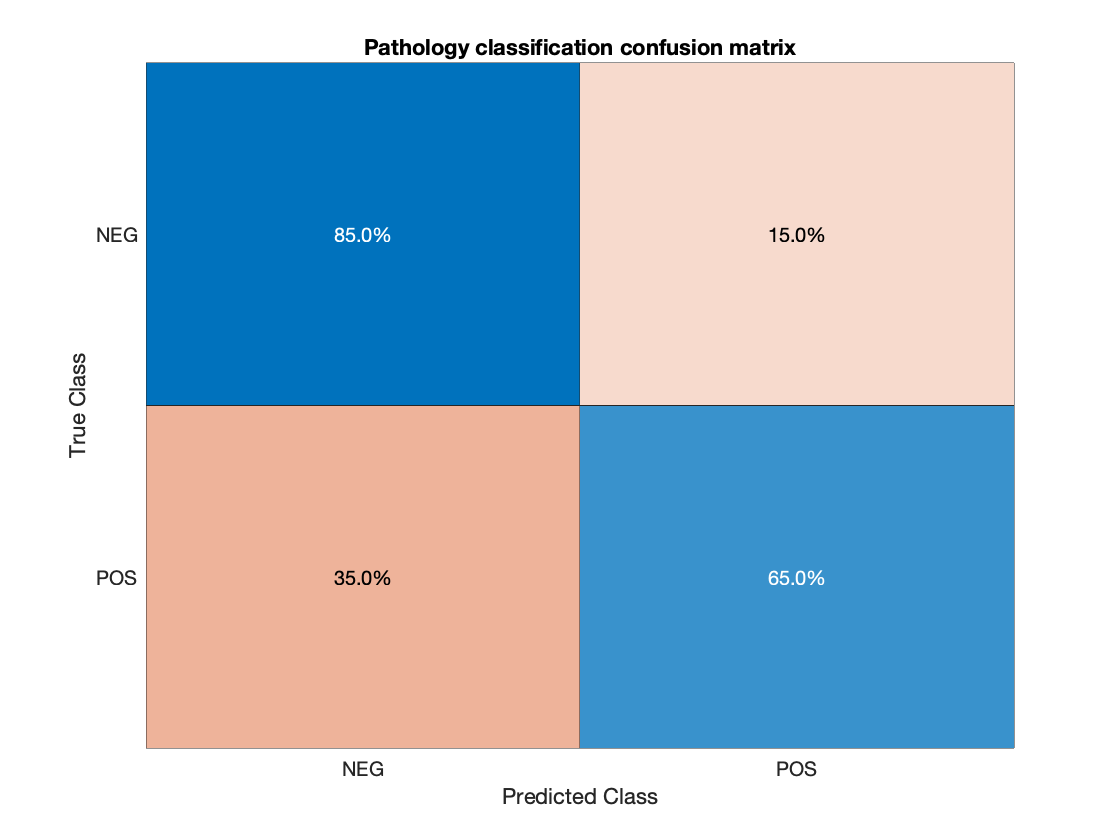

AUC = 0.6350

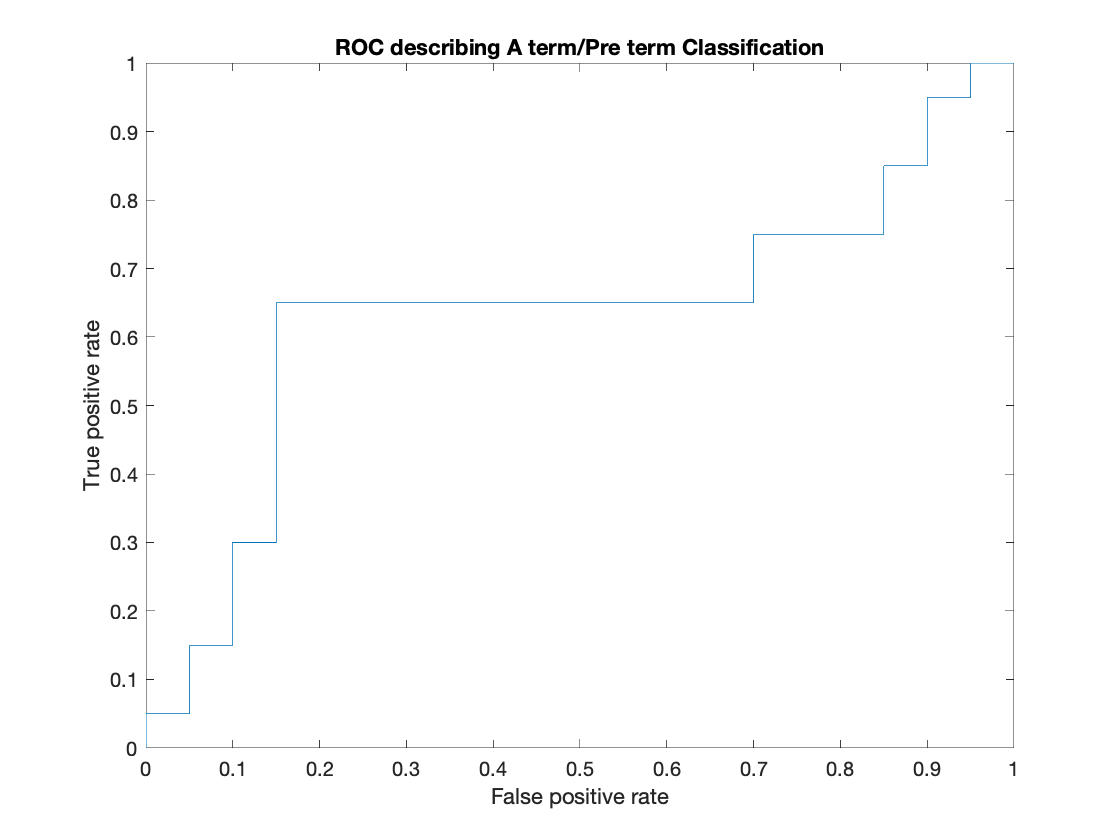

[trainedClassifier, validationAccuracy] = trainClassifier(Dataset,Kernel,KernelScale);

fprintf('The Trainig accuracy is %.1f%% \n',validationAccuracy*100);

The Trainig accuracy is 75.0% 


## TEST GENNAIO

%import data
[Dataset] = load_dataset(1,'sani3.csv','malati3.csv');

%extract the features previously selected
Dataset =  [ Dataset(:,fs) Dataset(:,end)]; % Parameters
Target = Dataset{:,end}; % Labels

Target = categorical(Target);


%40: 11 sani / 9 malati40
%3: 8 sani / 8 malati

predictions = predict(trainedClassifier.ClassificationSVM,Data); %Data

Error using classreg.learning.impl.CompactSVMImpl/score (line 68)
You must pass X as a matrix with 9 columns.

Error in classreg.learning.classif.CompactClassificationSVM/score (


cm = confusionchart(Target,predictions,'Normalization','row-normalized');
cm.Title = 'Pathology classification confusion matrix';


%POS sono malati, NEG sono sani